1. 시간 t에 따른신호가다음과같이주어진다고하자.

f(t) = e−0.12t sin(5t) + 0.3cos(2t) 

단, 0 ≤t≤30이고, MATLAB에서는 t=0:0.01:30으로 정의한다. 

clear; clc; close all;

(a) t와 f(t)를 계산한 뒤, plot을 이용하여 그래프를 그리시오. 

% (a) t와 f(t) 계산
t = 0 : 0.01 : 30;
f = exp(-0.12*t).*sin(5*t) + 0.3*cos(2*t);

figure;
plot(t, f, 'b');
hold on;
grid on;

(b) 다음 두보조곡선을같은그래프에함께표시하시오. 

u(t) = e−0.12t + 0.3, l(t) = −e−0.12t − 0.3 

단, hold on을 사용할 것. 

% (b) 보조곡선 u(t), l(t)
u = exp(-0.12*t) + 0.3;
l = -exp(-0.12*t) - 0.3;

plot(t, f, 'b');   % 원래 함수
hold on;           % 같은 그래프에 추가로 그림

plot(t, u, 'r--'); % 위 보조곡선
plot(t, l, 'g--'); % 아래 보조곡선

grid on;
legend('f(t)', 'u(t)', 'l(t)');
title('f(t) with auxiliary curves');
xlabel('t');
ylabel('Value');

(c) MATLAB의 find를 이용하여 다음 조건을만족하는index를 찾으시오.

 f(k) > f(k −1) and f(k) >f(k+1) 

즉, 양쪽이웃값보다큰점을국소최대값후보로정의한다.

% (c) find를 이용하여 국소 최대값 후보 index 찾기
idx = find(f(2:end-1) > f(1:end-2) & f(2:end-1) > f(3:end)) + 1;


(d) 찾은 국소 최대값 후보들을 그래프 위에 원 표시로나타내시오. 

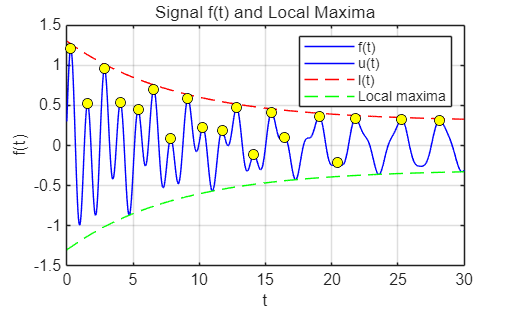

% (d) 국소 최대값 후보 그래프 위에 원 표시
plot(t(idx), f(idx), 'ko', 'MarkerFaceColor', 'y');

xlabel('t');
ylabel('f(t)');
title('Signal f(t) and Local Maxima');
legend('f(t)', 'u(t)', 'l(t)', 'Local maxima');

(e) 국소 최대 값 후보들의 t값과 f(t)값을 하나의 행렬 또는 table형태로 출력하시오.

% (e) 국소 최대값 후보들의 t값과 f(t)값 출력
result = table(t(idx)', f(idx)', ...
    'VariableNames', {'t_value', 'f_value'});

disp(result);

    t_value    f_value 
    _______    ________

       0.3       1.2098
      1.57      0.52828
      2.84      0.95686
      4.04       0.5337
      5.38      0.44424
      6.56      0.70239
      7.85      0.08978
      9.14      0.58298
     10.28       0.2222
     11.72      0.18078
     12.82      0.46719
     14.13      -0.1166
     15.46      0.41179
     16.44      0.10089
     19.06      0.36202
     20.41     -0.21369
      21.8      0.33804
     25.28      0.31941
     28.15      0.31064



2. 다음 2변수함수 를고려하자.

MATLAB에서 z = sin(xy) 1 +x2+y2 

x =−5:0.05 : 5, y =−5:0.05 : 5 로정의하고,

meshgrid를 이용하여 격자 행렬X,Y를만든다.

(a)원소별연산을사용하여행렬Z를계산하시오. 

clear; clc; close all;

% x, y 정의
x = -5 : 0.05 : 5;
y = -5 : 0.05 : 5;

% meshgrid 생성
[X, Y] = meshgrid(x, y);

% Z 계산
Z = sin(X .* Y) ./ (1 + X.^2 + Y.^2);

(b) mesh(X,Y,Z)를이용하여3차원그래프를그리시오. 

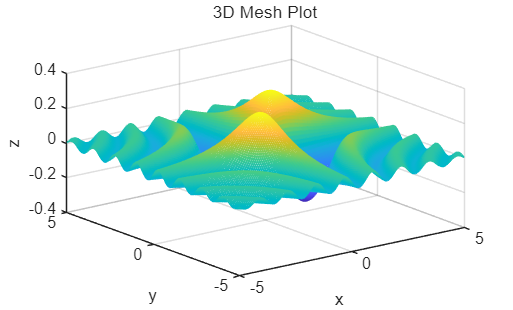

% (b) mesh 그래프
figure;
mesh(X, Y, Z);

xlabel('x');
ylabel('y');
zlabel('z');
title('3D Mesh Plot');
grid on;

(c) contour(X,Y,Z,25)를이용하여등고선그래프를그리시오. 

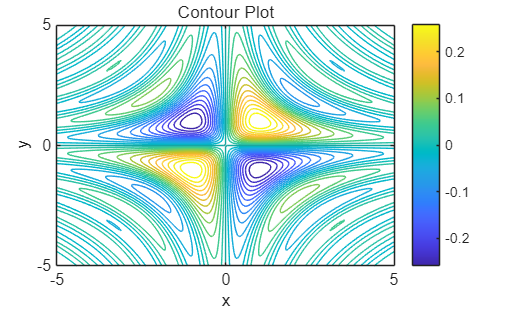

% (c) contour 그래프
figure;
contour(X, Y, Z, 25);

xlabel('x');
ylabel('y');
title('Contour Plot');
colorbar;
grid on;

(d) abs(Z)와max를이용하여|Z|의최댓값을구하시오. 

% (d) |Z|의 최댓값
maxVal = max(abs(Z(:)));

disp('Maximum value of |Z|:');

Maximum value of |Z|:


disp(maxVal);

    0.2805



(e) find또는ind2sub를이용하여|Z|가최대가되는위치의x좌표와y좌표를출력하시오. (참고: ind2sub는하나의선형인덱스(linear index)를행(row),열(column)인덱스로 변환하는함수. [row,col]=ind2sub(size(A), idx)처럼사용함)

% (e) |Z|가 최대가 되는 위치의 x, y 좌표
idx = find(abs(Z) == maxVal);

[row, col] = ind2sub(size(Z), idx);

x_max = X(row, col);
y_max = Y(row, col);

disp('Coordinates where |Z| is maximum:');

Coordinates where |Z| is maximum:


disp([x_max, y_max]);

    -1    -1     1     1    -1    -1    -1    -1
    -1    -1     1     1     1     1     1     1
    -1    -1     1     1    -1    -1    -1    -1
    -1    -1     1     1     1     1     1     1



3.다음행렬 A=    7 2 1 2 6 −2 1 −2 5    에대하여MATLAB을이용하여고유값과고유벡터를분석하시오. 

%% 3번 문제
clear; clc;

% 행렬 A 정의
A = [7 2 1;
     2 6 -2;
     1 -2 5];


(a) [V,D]=eig(A)를이용하여고유벡터행렬V와고유값행렬D를구하시오. 

% (a) 고유벡터 행렬 V와 고유값 행렬 D
[V, D] = eig(A);

disp('고유벡터 matrix V:');

고유벡터 matrix V:


disp(V);

    0.4219    0.5548    0.7171
   -0.6189   -0.4018    0.6749
   -0.6626    0.7285   -0.1738




disp('고유값 matrix D:');

고유값 matrix D:


disp(D);

    2.4953         0         0
         0    6.8646         0
         0         0    8.6400



(b) diag(D)를이용하여고유값들을벡터로추출하시오. 

% (b) 고유값들을 벡터로 추출
eigenvalues = diag(D);

disp('고유값들:');

고유값들:


disp(eigenvalues);

    2.4953
    6.8646
    8.6400



(c) max를이용하여가장큰고유값λmax과그위치index를구하시오.

% (c) 가장 큰 고유값과 위치 index
[lambda_max, index] = max(eigenvalues);

disp('Largest 고유값:');

Largest 고유값:


disp(lambda_max);

    8.6400




disp('Index of largest 고유값:');

Index of largest 고유값:


disp(index);

     3



(d)가장큰고유값에대응하는고유벡터v를V에서추출하시오.

% (d) 가장 큰 고유값에 대응하는 고유벡터
v = V(:, index);

disp('가장 큰 고유값에 대응하는 고유벡터:');

가장 큰 고유값에 대응하는 고유벡터:


disp(v);

    0.7171
    0.6749
   -0.1738



(e) v/norm(v)를이용하여v를단위벡터로변환하시오.

% (e) 단위벡터로 변환
v_unit = v / norm(v);

disp('Unit eigenvector:');

Unit eigenvector:


disp(v_unit);

    0.7171
    0.6749
   -0.1738



(f)Av−λmaxv를계산하여영벡터에가까운지확인하시오.

% (f) Av - lambda_max*v 계산
check = A*v - lambda_max*v;

disp('A*v - lambda_max*v:');

A*v - lambda_max*v:


disp(check);

   1.0e-14 *

   -0.0888
    0.3553
    0.0444



4.다음데이터행렬X는5개의관측값과3개의변수로이루어진데이터라고하자. X=         2 5 1 4 8 3 6 11 7 9 15 10 13 20 14         

%% 4번 문제
clear; clc;

% 데이터 행렬 X
X = [2 5 1;
     4 8 3;
     6 11 7;
     9 15 10;
     13 20 14];

(a) mean(X)를이용하여각열의평균을계산하시오.

% (a) 각 열의 평균 계산
mean_X = mean(X);

disp('Column means:');

Column means:


disp(mean_X);

    6.8000   11.8000    7.0000



(b)각열평균을제거한중심화행렬 Xc=X−mean(X) 를계산하시오. 

% (b) 중심화 행렬 Xc 계산
Xc = X - mean_X;

disp('Centered matrix Xc:');

Centered matrix Xc:


disp(Xc);

   -4.8000   -6.8000   -6.0000
   -2.8000   -3.8000   -4.0000
   -0.8000   -0.8000         0
    2.2000    3.2000    3.0000
    6.2000    8.2000    7.0000



(c)S=X′ cXc를계산하시오. 

% (c) S = Xc'' * Xc 계산
S = Xc' * Xc;

disp('Matrix S:');

Matrix S:


disp(S);

   74.8000  101.8000   90.0000
  101.8000  138.8000  123.0000
   90.0000  123.0000  110.0000



(d) eig(S)를이용하여S의고유값을계산하시오. 

% (d) S의 고유값 계산
[V, D] = eig(S);

disp('Eigenvalue matrix D:');

Eigenvalue matrix D:


disp(D);

    0.0473         0         0
         0    0.8388         0
         0         0  322.7139




% 고유값 벡터 추출
eigenvalues = diag(D);

disp('Eigenvalues:');

Eigenvalues:


disp(eigenvalues);

    0.0473
    0.8388
  322.7139



(e) max를이용하여가장큰고유값을찾으시오. 

% (e) 가장 큰 고유값 찾기
[max_eigenvalue, idx] = max(eigenvalues);

disp('Largest eigenvalue:');

Largest eigenvalue:


disp(max_eigenvalue);

  322.7139



(f)가장큰고유값에대응하는고유벡터를출력하시오

% (f) 가장 큰 고유값에 대응하는 고유벡터
principal_vector = V(:, idx);

disp('Eigenvector corresponding to largest eigenvalue:');

Eigenvector corresponding to largest eigenvalue:


disp(principal_vector);

    0.4806
    0.6556
    0.5824



5. 다음 연립방정식을MATLAB으로풀고두계산방법을비교하시오.        5x +2y−z =8 −2x+6y+3z =5 x−y+7z =12 

(a) 계수행렬 A와상수벡터b를정의하시오. 

clear; clc;

% (a) 계수행렬 A와 상수벡터 b 정의
A = [5 2 -1;
    -2 6 3;
     1 -1 7];

b = [8;
     5;
     12];


(b) x1=inv(A)*b를 이용하여 해를 구하시오. 

% (b) inv(A)*b 를 이용한 해
x1 = inv(A) * b;

disp('Solution using inv(A)*b:');

Solution using inv(A)*b:


disp(x1);

    1.6692
    0.6084
    1.5627



(c) x2=A\b를 이용하여 해를 구하시오. 

% (c) A\b 를 이용한 해
x2 = A \ b;

disp('Solution using A\b:');

Solution using A\b:


disp(x2);

    1.6692
    0.6084
    1.5627



(d) x1-x2를 계산하여 두 결과의 차이를출력하시오.

% (d) 두 결과의 차이
difference = x1 - x2;

disp('Difference between x1 and x2:');

Difference between x1 and x2:


disp(difference);

   1.0e-15 *

    0.2220
    0.2220
         0



(e) det(A)를 계산하시오. 계산 결과가 0이 아니면 해가유일하게존재한다고판단하시오.

% (e) det(A) 계산
detA = det(A);

disp('det(A) =');

det(A) =


disp(detA);

   263




% 해의 유일성 판단
if detA ~= 0
    disp('A는 가역행렬이므로 해가 유일하게 존재한다.')
else
    disp('A는 가역행렬이 아니므로 해가 유일하지 않다.')
end

A는 가역행렬이므로 해가 유일하게 존재한다.


6. 다음 2변수함수 를고려하자.MATLAB에서 z =e−0.08(x2+y2) cos(3x)sin(2y) x =−6:0.05 : 6, 로정의한다. y =−6:0.05 : 6 

(a) meshgrid를 이용하여 X,Y를 만들고 Z를 계산하시오. 

clear; clc; close all;

% x, y 정의
x = -6 : 0.05 : 6;
y = -6 : 0.05 : 6;

% (a) meshgrid 및 Z 계산
[X, Y] = meshgrid(x, y);

Z = exp(-0.08 * (X.^2 + Y.^2)) ...
    .* cos(3 * X) ...
    .* sin(2 * Y);


(b) surf(X,Y,Z)를 이용하여 3차원 표면 그래프를 그리시오. 

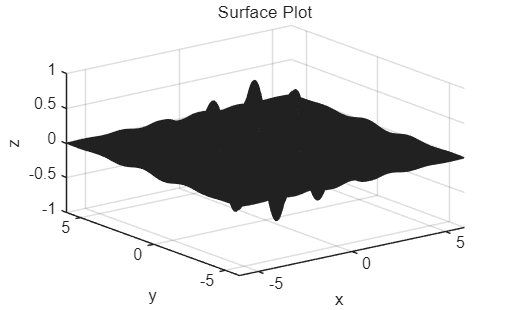

% (b) surf 그래프
figure;
surf(X, Y, Z);

xlabel('x');
ylabel('y');
zlabel('z');
title('Surface Plot');
grid on;

(c) contour(X,Y,Z,30)을 이용하여 등고선 그래프를 그리시오. 

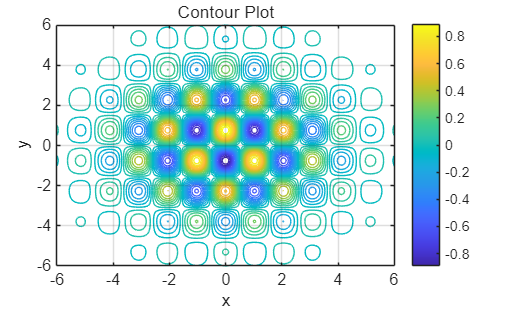

% (c) contour 그래프
figure;
contour(X, Y, Z, 30);

xlabel('x');
ylabel('y');
title('Contour Plot');
colorbar;
grid on;

(d) max(Z(:))와 min(Z(:))을 이용하여 Z의 최대값과 최소값을 구하시오. 

% (d) 최대값과 최소값
maxZ = max(Z(:));
minZ = min(Z(:));

disp('Maximum value of Z:');

Maximum value of Z:


disp(maxZ);

    0.9536




disp('Minimum value of Z:');

Minimum value of Z:


disp(minZ);

   -0.9536



(e) ind2sub를 이용하여 최대값과 최소값이 발생하는(x,y) 좌표를 각각출력하시오.

% (e) 최대값 위치 찾기
idx_max = find(Z == maxZ);

[row_max, col_max] = ind2sub(size(Z), idx_max);

x_max = X(row_max, col_max);
y_max = Y(row_max, col_max);

disp('Coordinates of maximum value:');

Coordinates of maximum value:


disp([x_max, y_max]);

         0    0.7500




% 최소값 위치 찾기
idx_min = find(Z == minZ);

[row_min, col_min] = ind2sub(size(Z), idx_min);

x_min = X(row_min, col_min);
y_min = Y(row_min, col_min);

disp('Coordinates of minimum value:');

Coordinates of minimum value:


disp([x_min, y_min]);

         0   -0.7500



7. 어떤 서버시스템에서사용자수n에따른평균응답시간T가다음과같이측정되었다. n =[50, 100, 200, 400, 800, 1600] T =[14, 19, 30, 51, 92, 170]

(a) plot(n,T,’o-’)를 이용하여 일반 그래프를 그리시오.

clear; clc; close all;

% 데이터 정의
n = [50, 100, 200, 400, 800, 1600];
T = [14, 19, 30, 51, 92, 170];
% (d) 1 x 3 subplot으로 세 그래프 배치

% (a) 일반 그래프
subplot(1, 3, 1);
plot(n, T, 'o-');
grid on;
xlabel('n');
ylabel('T');
title('plot(n,T)');



(b) semilogx(n,T,’o-’)를 이용하여 x축 로그 그래프를 그리시오. 

% (b) x축 로그 그래프
subplot(1, 3, 2);
semilogx(n, T, 'o-');
grid on;
xlabel('n');
ylabel('T');
title('semilogx(n,T)');

(c) semilogy(n,T,’o-’)를 이용하여 y축 로그 그래프를 그리시오. 

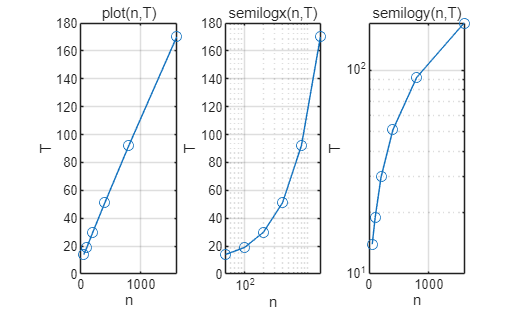

% (c) y축 로그 그래프
subplot(1, 3, 3);
semilogy(n, T, 'o-');
grid on;
xlabel('n');
ylabel('T');
title('semilogy(n,T)');

(d) 세 그래프를1×3subplot으로 배치하시오. 

%위a에 참조

(e) 세 그래프 중 점들이 가장직선에가깝게보이는그래프를선택하고,그그래프이름을 Live Script에 문장으로 작성하시오.

% (e) 가장 직선에 가까운 그래프 선택
disp('세 그래프 중 plot 그래프가 가장 직선에 가깝게 보인다.')

세 그래프 중 plot 그래프가 가장 직선에 가깝게 보인다.


8. 어떤 도시의하루전력사용량P(t)가다음함수로모델링된다.

 P(t) = 50+18sin πt 12 +6cos πt 4 

여기서t는시간(hour)을의미하며, 0≤t≤24이다.MATLAB에서는t=0 : 0.01 : 24로 정의한다. 

(a) t와P(t)를계산하고그래프를그리시오.

%% 8번 문제
clear; clc; close all;

% 시간 정의
t = 0 : 0.01 : 24;

% (a) 전력 사용량 P(t) 계산
P = 50 + 18*sin(pi*t/12) + 6*cos(pi*t/4);

% 그래프
figure;
plot(t, P, 'b', 'LineWidth', 1.5);
hold on;
grid on;

xlabel('Time (hour)');
ylabel('Power Usage');
title('Power Consumption P(t)');

 (b) max(P)를이용하여최대전력사용량을구하시오. 

% (b) 최대 전력 사용량
[Pmax, idx_max] = max(P);

disp('Maximum power usage:');

Maximum power usage:


disp(Pmax);

   72.1731



(c)최대값이발생하는index를이용하여최대전력사용량이발생한시간t를출력하시오. 

% (c) 최대값 발생 시간
t_max = t(idx_max);

disp('Time of maximum power usage:');

Time of maximum power usage:


disp(t_max);

    7.5000



(d) min(P)를이용하여최소전력사용량과그발생시간을출력하시오. 

% (d) 최소 전력 사용량과 발생 시간
[Pmin, idx_min] = min(P);

t_min = t(idx_min);

disp('Minimum power usage:');

Minimum power usage:


disp(Pmin);

   27.8269




disp('Time of minimum power usage:');

Time of minimum power usage:


disp(t_min);

   19.5000



(e)최대점과최소점을그래프위에서로다른marker로표시하시오

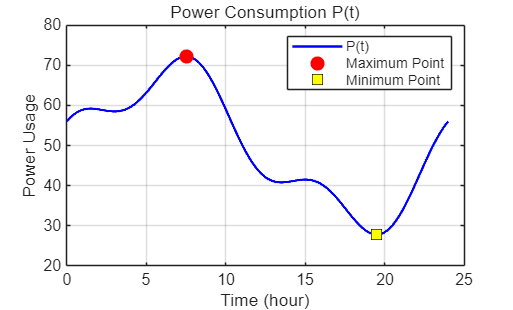

% (e) 최대점과 최소점 표시
plot(t_max, Pmax, 'ro', 'MarkerSize', 8, ...
    'MarkerFaceColor', 'r');

plot(t_min, Pmin, 'ks', 'MarkerSize', 8, ...
    'MarkerFaceColor', 'y');

legend('P(t)', 'Maximum Point', 'Minimum Point');

9.한연구자는세개의센서가비슷한방향의데이터를측정하는지확인하려고한다.다음데이터 행렬에서각열은하나의센서측정값을의미한다. 

X=         1 3 0 2 5 1 4 8 3 7 12 5 11 17 9         

(a)세열벡터를각각x1,x2,x3로정의하시오. 

%% 9번 문제
clear; clc;

% 데이터 행렬 X
X = [1 3 0;
     2 5 1;
     4 8 3;
     7 12 5;
     11 17 9];

% (a) 각 열벡터 정의
x1 = X(:,1);
x2 = X(:,2);
x3 = X(:,3);

(b)내적과norm을이용하여x1,x2사이의각도를degree단위로계산하시오. 

% (b) x1과 x2 사이의 각도
theta12 = acosd( dot(x1,x2) / (norm(x1)*norm(x2)) );

disp('Angle between x1 and x2:');

Angle between x1 and x2:


disp(theta12);

    7.1357



(c)같은방법으로x1,x3,x2,x3사이의각도를degree단위로계산하시오. 

% (c) x1과 x3, x2와 x3 사이의 각도
theta13 = acosd( dot(x1,x3) / (norm(x1)*norm(x3)) );

theta23 = acosd( dot(x2,x3) / (norm(x2)*norm(x3)) );

disp('Angle between x1 and x3:');

Angle between x1 and x3:


disp(theta13);

    6.1221




disp('Angle between x2 and x3:');

Angle between x2 and x3:


disp(theta23);

   12.8186



(d)세각도를하나의벡터theta에저장하시오. 

% (d) 각도를 벡터 theta에 저장
theta = [theta12, theta13, theta23];

disp('Theta vector:');

Theta vector:


disp(theta);

    7.1357    6.1221   12.8186



(e) min(theta)를이용하여가장작은각도를찾고,가장방향이비슷한두센서번호를 출력하시오.

% (e) 가장 작은 각도 찾기
[min_theta, idx] = min(theta);

disp('Smallest angle:');

Smallest angle:


disp(min_theta);

    6.1221




% 가장 비슷한 센서 번호 출력
if idx == 1
    disp('Sensors 1 and 2 are most similar.');
elseif idx == 2
    disp('Sensors 1 and 3 are most similar.');
else
    disp('Sensors 2 and 3 are most similar.');
end

Sensors 1 and 3 are most similar.


10.한전기회로에서전류i1,i2,i3는다음선형시스템을만족한다.    9 −2 −1 −2 8 −3 −1 −3 10       i1 i2 i3   =    15 7 11    

%% 10번 문제
clear; clc;



(a)계수행렬A와상수벡터b를정의하시오. 

% (a) 계수행렬 A와 상수벡터 b 정의
A = [9 -2 -1;
    -2  8 -3;
    -1 -3 10];

b = [15;
     7;
     11];

(b) I=A\b를이용하여전류벡터I를계산하시오.

% (b) I = A\b 를 이용하여 전류 벡터 계산
I = A \ b;

disp('Current vector I:');

Current vector I:


disp(I);

    2.3834
    2.2228
    2.0052



 (c) det(A)를계산하여A가가역행렬인지확인하시오. 

% (c) det(A)를 계산하여 A가 가역행렬인지 확인
detA = det(A);

disp('det(A) =');

det(A) =


disp(detA);

   579




if detA ~= 0
    disp('A는 가역행렬이다.')
else
    disp('A는 가역행렬이 아니다.')
end

A는 가역행렬이다.


(d) abs(I)를계산하시오. 

% (d) abs(I) 계산
absI = abs(I);

disp('Absolute values of currents:');

Absolute values of currents:


disp(absI);

    2.3834
    2.2228
    2.0052



(e) max(abs(I))를이용하여절댓값이가장큰전류와그전류의번호를출력하시오

% (e) 절댓값이 가장 큰 전류와 전류 번호 출력
[max_current, idx] = max(absI);

disp('절댓값이 가장 큰 전류:');

절댓값이 가장 큰 전류:


disp(max_current);

    2.3834




disp('전류 번호:');

전류 번호:


disp(idx);

     1



11.어떤음향시스템의출력신호가다음과같이모델링된다. y(t)=e−0.04t(sin(4t)+0.6sin(9t)) 여기서t는시간(sec)을의미하며, 0≤t≤40이다.MATLAB에서는t=0 : 0.01 : 40으로 정의한다

%% 11번 문제
clear; clc; close all;

% 시간 정의
t = 0 : 0.01 : 40;


(a) y(t)를 계산하고 그래프를 그리시오. 

% (a) y(t) 계산
y = exp(-0.04*t) .* (sin(4*t) + 0.6*sin(9*t));

% 그래프
figure;
plot(t, y, 'b');
hold on;
grid on;

xlabel('t');
ylabel('y(t)');
title('Output Signal y(t)');

(b) 다음 두보조곡선을계산하시오. u(t) = 1.6e−0.04t, l(t) = −1.6e−0.04t 

% (b) 보조곡선 계산
u = 1.6 * exp(-0.04*t);
l = -1.6 * exp(-0.04*t);

(c) y(t), u(t), l(t)를 같은 그래프에 표시하시오. 

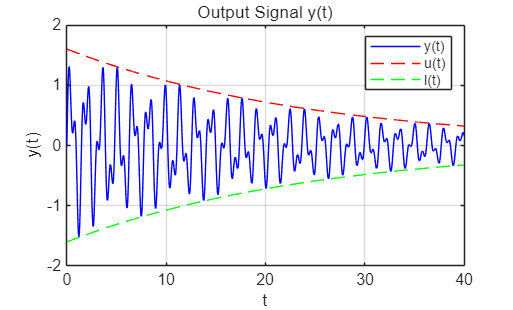

% (c) y(t), u(t), l(t)를 같은 그래프에 표시
plot(t, u, 'r--');
plot(t, l, 'g--');

legend('y(t)', 'u(t)', 'l(t)');

(d) semilogy(t,abs(y))를 이용하여 |y(t)|의 로그 스케일 그래프를 그리시오.

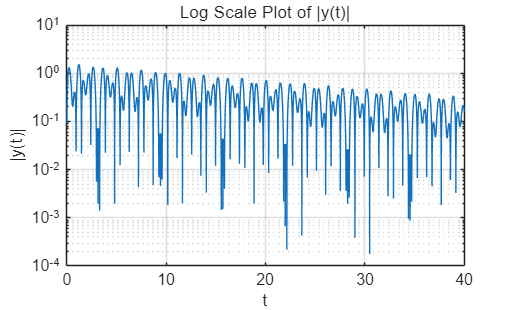

% (d) |y(t)|의 로그 스케일 그래프
figure;
semilogy(t, abs(y));

grid on;
xlabel('t');
ylabel('|y(t)|');
title('Log Scale Plot of |y(t)|');

(e) t = 0일 때의 u(t)와 t=40일 때의 u(t)를 계산하여 출력하시오.

% (e) t=0 과 t=40 에서의 u(t) 계산
u0 = 1.6 * exp(-0.04*0);
u40 = 1.6 * exp(-0.04*40);

disp('u(0) =');

u(0) =


disp(u0);

    1.6000




disp('u(40) =');

u(40) =


disp(u40);

    0.3230



12. 어떤 머신러닝모델의학습손실(loss)이 epoch에 따라 다음과 같이 감소하였다. 

epoch = [1, 2, 5, 10, 20, 50, 100, 200] 

loss = [3.1, 2.4, 1.7, 1.2, 0.83, 0.36, 0.14, 0.06] 

(a) plot(epoch,loss,’o-’)를 이용하여 일반 그래프를 그리시오. 

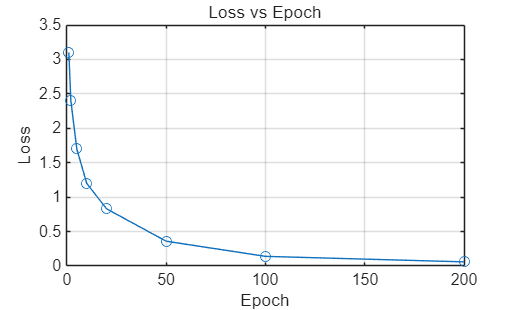

clear; clc; close all;

epoch = [1, 2, 5, 10, 20, 50, 100, 200];
loss = [3.1, 2.4, 1.7, 1.2, 0.83, 0.36, 0.14, 0.06];

% (a) 일반 그래프
figure;
plot(epoch, loss, 'o-');

grid on;
xlabel('Epoch');
ylabel('Loss');
title('Loss vs Epoch');

(b) semilogy(epoch,loss,’o-’)를 이용하여 로그 스케일 그래프를 그리시오. 

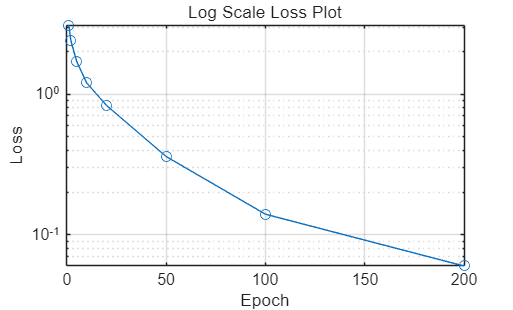

% (b) 로그 스케일 그래프
figure;
semilogy(epoch, loss, 'o-');

grid on;
xlabel('Epoch');
ylabel('Loss');
title('Log Scale Loss Plot');

(c) 다음 비율벡터를계산하시오. r(k) = loss(k +1) loss(k) 단, MATLAB 코드에서는loss(2:end)./loss(1:end-1)를 사용할 것. 

% (c) 비율 벡터 r 계산
r = loss(2:end) ./ loss(1:end-1);

disp('Ratio vector r:');

Ratio vector r:


disp(r);

    0.7742    0.7083    0.7059    0.6917    0.4337    0.3889    0.4286



(d) 비율 벡터r의평균을계산하시오. 

% (d) 비율 벡터 평균 계산
mean_r = mean(r);

disp('평균 ratio:');

평균 ratio:


disp(mean_r);

    0.5902



(e) 평균비율이1보다작으면loss가전반적으로감소한다고판단하고,그결과를LiveScript 에문장으로작성하시오.

% (e) 평균 비율을 이용한 판단
if mean_r < 1
    disp('loss가 전체적으로 감소하는 경향을 보인다');
else
    disp('loss가 전체적으로 감소하지 않는다.');
end

loss가 전체적으로 감소하는 경향을 보인다
